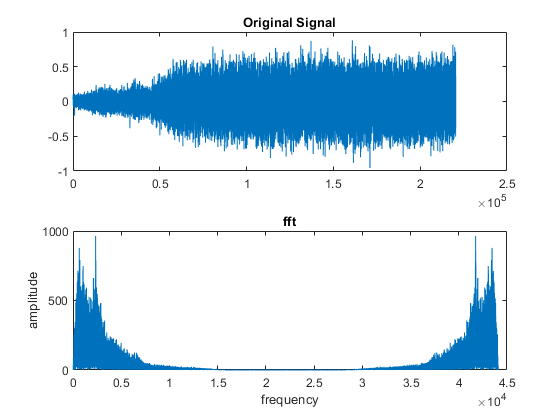

clear; clc;
[s,fs]=audioread('combined.wav');
FS=length(s); % Length of x;
f=0:fs/FS:(FS-1)*fs/FS; %Generate a one-dimensional array to f
S=fft(s,FS); %10000 points FFT
magS=abs(S); 
subplot(2,1,1);plot(s);
title('Original Signal');
subplot(2,1,2);plot(f,magS);title('fft');
xlabel('frequency');ylabel('amplitude');

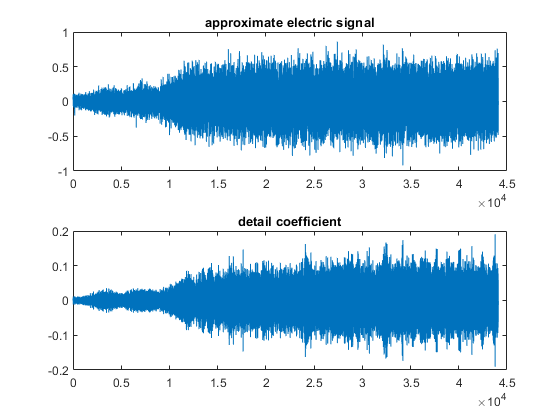

%%%one level decomposition
lengthS=length(s);
[cA1,cD1]=dwt(s,'db1');
%%%reconstruct the signal
A1=idwt(cA1,[],'db1',lengthS);
D1=idwt([],cD1,'db1',lengthS);
%%%display approximate details
figure(2);
title('approximate coefficient and detail coefficient');
subplot(2,1,1);plot(f,A1);title('approximate electric signal');
subplot(2,1,2);plot(f,D1);title('detail coefficient');

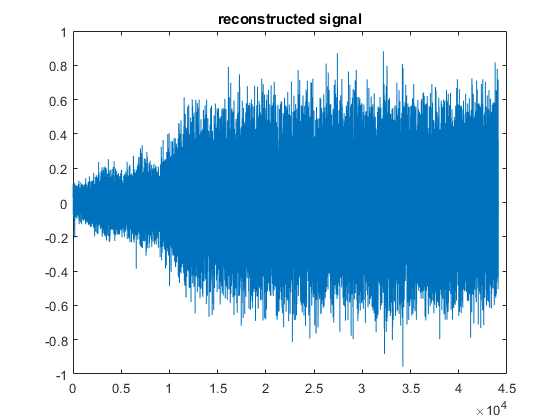

%%%reconstruct original signal
A0=idwt(cA1,cD1,'db1',lengthS);
figure(3);
plot(f,A0);
title('reconstructed signal');

err = max(abs(s-A0)); 